# Markov Modeling of a Zombie Outbreak

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

Markov modeling is a statistical technique used to analyze systems with discrete states and transitions between them. It has been widely applied in biology to study protein folding, gene regulatory networks, and ecological processes. Linear algebra plays a crucial role in Markov modeling by providing the mathematical framework for representing and analyzing the system's states and short- and long-term transitions. Matrices represent the transition probabilities between states, and vector operations enable calculations such as steady-state analysis, eigenvalue computations, and solving systems of linear equations. Through linear algebra, Markov models can be efficiently analyzed and manipulated to gain insights into the behavior and dynamics of complex systems.

Analyzing a constant-probability Markov model of a zombie outbreak can provide insights into the spread and containment strategies, allowing policymakers to make informed decisions to mitigate the impact and control the outbreak effectively.

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Define the states of the system

In this scenario of a zombie outbreak, initially, all humans are considered susceptible. At each time step, if a human becomes infected, they will transition to the infected state and then to the zombie state in the next time step. Once a human becomes a zombie, they remain in that state and do not revert back to being human. This model assumes that there are no recovery or cure mechanisms.

        $S$ = number of susceptible humans

        $I$ = number of infected humans

        $Z$ = number of zombies

## Determine the transition probabilities between states 

The top three factors that influence whether a human comes in contact with a zombie in a zombie outbreak scenario are:

- **Population Density:** Higher population density increases the chances of human-zombie encounters as more individuals are present in a given area, leading to a higher probability of contact.

- **Movement Patterns:** Human mobility and movement patterns significantly impact the likelihood of encountering zombies. Factors like travel patterns, migration, and transportation systems can influence the frequency and duration of human-zombie interactions.

- **Awareness and Precautionary Measures:** The level of awareness and adherence to precautionary measures, such as barricading, staying indoors, or implementing quarantine protocols, can reduce the chances of humans coming into contact with zombies, thus influencing the overall spread of the outbreak.

We're building a simple model, initially, so we can summarize this as a probability, $\alpha$, that a susceptible human is infected at each time step. Thus, the transition probability from $S$ to $I$ is $\alpha_{SI}$. All non-infected humans will remain susceptible, so the transition probability from $S$ to $S$ is $1-\alpha_{SI}$. All infected humans will become zombies, so the transition probability from $I$ to $Z$ is 1. Because we have assumed that zombies have no possibility for recovery, the complete transition diagram looks like this:

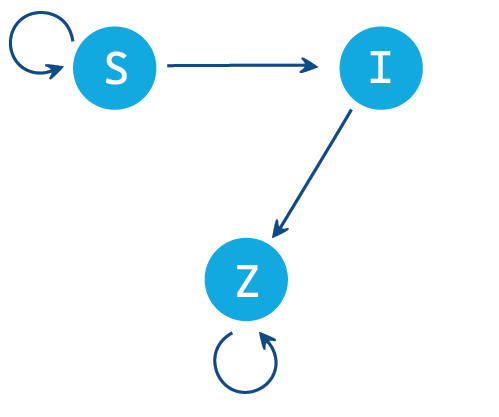

### Construct a transition matrix 

A transition matrix identifies the probabilities of transitioning from each state to every other state. 


$$S$$
              
$$I$$
              
$$Z$$



$$\matrix{S \cr I \cr Z}$$
   
$$\pmatrix{P(\text{S}\rightarrow\text{S}) & P(\text{S}\rightarrow\text{I}) & P(\text{S}\rightarrow\text{Z}) \cr 
P(\text{I}\rightarrow\text{S}) & P(\text{I}\rightarrow\text{I}) & P(\text{I}\rightarrow\text{Z}) \cr 
P(\text{Z}\rightarrow\text{S}) & P(\text{Z}\rightarrow\text{I}) & P(\text{Z}\rightarrow\text{Z})}$$
    

Because we track the allocation of our entire population at each step, this type of transition matrix is also called a stochastic probability matrix. A stochastic matrix has the property that the sum of values in each row is 1. This will be important to our analysis, but you can define Markov models that are not built with stochastic transition matrices.

 **Reflect**. 

- What is the transition diagram for an identity transition matrix, $\displaystyle T = \pmatrix{1 & 0 & 0 \cr 0 & 1 & 0 \cr 0 & 0 & 1}$?

- Is this transition matrix set up to be multiplied by populations on the left $\pmatrix{S & I & Z}$ or on the right $\pmatrix{S\cr I \cr Z}$? Why?

 **Exercise 1. **Fill in the values to create the transition matrix `T`, in terms of `alpha_SI`, for our system as described in the previous section.

**Hint:** Simple models frequently have many zeros in their transition matrices. 

% The default value of TransitionMatrix is simply an identity matrix 
% which does not model this system.
syms alpha_SI
T = [1 0 0;
    0 1 0;
    0 0 1]
CheckExercise1(T,alpha_SI)

## Analyze the model

To begin analyzing a Markov model, the first step is to determine the initial conditions of the system. This involves specifying the initial distribution of individuals across the different states of the model. For example, in this zombie outbreak scenario, the initial conditions involve assigning the number of susceptible humans, infected humans, and zombies at the beginning of the outbreak. Let's assume a total population of 1,000,000, of which 999,999 are initially susceptible humans and one is infected. This gives us initial conditions of

$S_0 = 999,999$    $I_0 = 1$      and      $Z_0 = 0$

P0 = [999999 1 0];

Set a value for $\alpha$:

AlphaVal = 0.01;
TransitionMatrix = subs(T,alpha_SI,AlphaVal)

How many time steps do you want to take?

TimeSteps = 100;

Round the answer to account for the fact that we must work with entire people:

PTimeSteps = round(P0*TransitionMatrix^TimeSteps,0);

Then, display the results:

disp(array2table(PTimeSteps,...
    "VariableNames",["Susceptible" "Infected" "Zombies"],...
    "RowNames",string(TimeSteps)+" steps"))

  **Try**.

- Change the number of time steps. Can you see how the matrix model is working?

- Change the value of $\alpha$. How does this impact the number of zombies over time?

- Extract the code computing the transition matrix from the initial state $P_0$ to the final state of the population. What does that matrix tell you? 

% Paste the code for the transition matrix from P0 to PTimeSteps here


**Hint:** This is part of the calculation of `PTimeSteps`.

 **Reflect**.

- What will happen as we let `TimeSteps` $\to \infty$?

- Did the initial population `P0` matter to the final result?

- Does this model make sense? Why or why not?

### Linear Algebra

Recall that a square matrix $M$has a right eigenvector $v$ with eigenvalue $\lambda$ if $Mv = \lambda v$. Usually, the approach to finding such eigenvalues involves solving the equation $\text{det}\left(M-\lambda I) = 0$. Consider the unique properties of a probability matrix like the transition matrix for a Markov model.

  **Try**. What is the sum of values in each row of a transition matrix, that is $\displaystyle \sum_j T_{ij}$?

  **Pro-tip**.MATLAB is a column-oriented language, so the function `sum(T)` or `sum(T,1)` would calculate the sum of each column, $\displaystyle \sum_i T_{ij}$. Because we want the rows, we can use `sum(T,2)` to indicate that we want a sum in the second dimension. 

 **Reflect**. Each member of a state must be allocated to a new state, but there are no conditions about the sums of columns! What does it mean for a Markov model transition matrix to have a column sum less than 1? equal to 1? or greater than 1?

#### Finding an eigenvalue/eigenvector pair

 **Exercise 2. **Using the definition of a right eigenvector and the properties of a stochastic transition matrix to identify an eigenvalue/eigenvector pair.

### Steady State

Steady-state refers to a condition where a system reaches a stable and unchanging state over time. In the context of Markov modeling, it represents the long-term equilibrium distribution of probabilities for each state, indicating the relative likelihood of being in a particular state in the absence of external influences or changes. Let's try to describe this in equations:


$$\left(\overrightarrow{\text{Steady State Probabilities}}\right)*\left(\text{Transition Matrix}\right) = \overrightarrow{\text{Steady State Probabilities}}$$



$$\sum \left(\text{Steady State Probabilities}\right) = \sum_{k=1}^n p_k = 1$$


Alternatively, that first equation could be written as


$$\left(\overrightarrow{\text{Steady State Probabilities}}\right)*\left(\text{Transition Matrix}\right) - \overrightarrow{\text{Steady State Probabilities}} = \vec{0}$$


or, equivalently,

$\left(\overrightarrow{\text{Steady State Probabilities}}\right)*\left(\text{Transition Matrix}-\text{I}\right) = \vec{0}$.

The steady-state probabilities are a left eigenvector of the transition matrix with eigenvalue 1!

 **Warning: **This requires the existence of such a vector of steady-state probabilities. This does not always exist. 

Let's check the situation with our zombie model. In this case, because we are dealing with probability matrices, we can assume that $\alpha$ is real and nonnegative. Then, we can use the `eig()` function to compute eigenvalues and eigenvectors. 

assume(alpha_SI,"real")
assumeAlso(alpha_SI>=0)
[V,D] = eig(TransitionMatrix')

  **Try**. Check that the final column of `V`, when transposed, is a right eigenvector of `TransitionMatrix`.

  **Pro-tip**. The `eig` function in MATLAB has a slightly complicated signature. If you call 

you will get a column vector containing the eigenvalues. The output is somewhat different when the argument is a symbolic matrix, like `TransitionMatrix`. The left eigenvalues are not computed, and the third output indicates which eigenvalue corresponds to which eigenvector. 

With more than one output and a numeric matrix `M`, however, the signature is 

where `V` is a matrix where the columns are the right eigenvectors, `D` is a diagonal matrix with the eigenvalues on the diagonal, and `W` is a matrix whose columns are the left eigenvectors of `M`. 

 **Reflect**.

- Why do we want the left eigenvectors?

- What properties make an eigenvector a possible steady-state probability vector? Why?

### Improving the Outcome

We want to be able to handle a zombie outbreak without an apocalypse. Let's assume we find a vaccine that can be administered at the Infected stage that probabilistically counteracts the transition to zombie. In this case, a percentage $\beta$ will return from $I$ to $S$ while the remainder will continue to become zombies. 

  **Try**. Set up a new transition matrix called `TransitionMatrix2` in terms of `alpha_SI` and `beta_IS`. 

syms alpha_SI beta_IS real
TransitionMatrix2 = [1-alpha_SI 0 0;
                    0 1 0;
                    0 0 1]
                    

Calculate the left eigenvalues of the symbolic matrix by transposing before using the `eig` function. This step assumes that `alpha_SI` and `beta_IS` are real. 

[Vs,Ds] = eig(TransitionMatrix2')

Try to determine if there are values of `beta_IS` that will result in a steady state probability that is not "everyone becomes a zombie." Which values might work?

ChooseAnEigenvalue = 3;
MySoln = solve(Ds(ChooseAnEigenvalue,ChooseAnEigenvalue)==1,beta_IS,"ReturnConditions",true)

#### Test the result

Intuitively, the result that you found should make sense. The only way that an absorbing state, like becoming a zombie, can not dominate the entire model is if there are paths that never get there. What is the alternate steady-state result that you found?

TransitionMatrix3 = subs(TransitionMatrix2,beta_IS,MySoln.beta_IS)
[Vs3,Ds3] = eig(TransitionMatrix3')

### Can we save zombies?

Okay, we've established that the only way to prevent a zombie apocalypse, given an infinite time horizon, is to find a perfect treatment to apply at the infected stage. It is true that a perfect vaccine against infection would also suffice. What happens to our model if we posit that a brilliant scientist has discovered a method to cure zombies? Some zombies revert straight to the susceptible human stage, but others are only moved back to the infected stage. Let's assume $\beta_{IS} = 0.5$.

syms alpha_SI beta_IS gamma_ZS gamma_ZI real
assumeAlso(gamma_ZS+gamma_ZI <= 1)
assumeAlso(gamma_ZS>=0)
assumeAlso(gamma_ZI>=0)
assumeAlso(alpha_SI>=0)
assumeAlso(alpha_SI<=1)


Write an `ImprovedTransition` matrix that implements the Markov model described in terms of `alpha_SI`, `beta_IS`, `gamma_ZS`, and `gamma_ZI`.

ImprovedTransition = [1 0 0;
                      0 1 0;
                      0 0 1];
[Vfinal,Dfinal] = eig(ImprovedTransition')

 **Reflect**. 

- If at least one of $\gamma_{ZS}$ and $\gamma_{ZI}$ are nonzero, describe the steady-state probabilities for this system.

- Is there more than one solution for fixed values of $\alpha_{SI}$, $\gamma_{ZS}$, and $\gamma_{ZI}$? Why or why not?

- What happens if you change the assumptions about $\beta_{IS}$? 

## Ergodic Markov Chains

A Markov model is called ergodic if it is possible to get to every state from every other state. Notice that this results in a Markov model where the long-term analysis is independent of the initial population distribution. 

  **Try**. Design an ergodic Markov model with transition matrix `ErgodicTransitionMatrix`. Then, analyze its long-term behavior.

ErgodicTransitionMatrix = eye(3);



CheckErgodic(ErgodicTransitionMatrix)

**Note: **The original zombie model was an ergodic unichain with two transient states, $S$ and $I$, and one ergodic state $Z$. Any member of the population could end up in $Z$ after one or two time steps, but once in $Z$, there is no way to leave. 

### Alternative systems

Not every system will have a steady-state solution. Consider a stage Markov model of an insect like the mayfly. The stages are egg, nymph, subimago, imago. As with most biological systems, our understanding of the complexities has grown over time (c.f. [http://www.ephemeroptera-galactica.com/pubs/pub_c/pubcorbetp1957p243.pdf](http://www.ephemeroptera-galactica.com/pubs/pub_c/pubcorbetp1957p243.pdf) and [https://en.wikipedia.org/wiki/Mayfly](https://en.wikipedia.org/wiki/Mayfly)), but even a simple model can have significant explanatory power. 

 **Exercise 3.**

- Define a transition matrix for the mayfly lifecycle where eggs hatch into nymphs, nymphs molt into subimagos, subimagos molt into imagos, and imagos lay eggs and die. Assume, for the moment, that no eggs, nymphs, or subimagos die. 

- Start with a population of 3000 eggs, 0 nymphs, 0 subimagos, and 0 adults. Then, analyze this system to determine whether it has any steady-state solutions. Explain why or why not.

#### Improve the model

In an ecological system, assuming that all eggs, nymphs, and subimagos survive to reach the next stage is unrealistic. Let's remove a fraction of our mayflies at each stage. 

 **Exercise 3. **Assuming 20% of eggs survive to hatch into larvae, 25% of larvae survive to become subimagos, 20% of subimagos survive to become imagos, and 8% of imagos lay fertilized eggs. 

- How many eggs must be laid, on average, by each imago to have a stable population of mayflies so that there is the same number of eggs in the 100th generation?

- What happens to your analysis if 5% of eggs enter diapause, 15% of the eggs hatch, and the same 80% of the eggs die at each time step? Plot the results over 100 generations.

- Approximately how many fertilized eggs are required, on average, per successful imago to have a stable population after 100 generations? Plot the results. 

## Treating HIV patients

**Application.  **There is a real-world scenario that, for many years, was disturbingly like the zombie model discussed above. There are now treatments that effectively add additional states to our model, such as "vaccinated," which dramatically lowers the risk of infection, and "treated," which dramatically lowers the probability of moving out of the "infected" group. As outcomes began to improve, many studies have tried to determine how well clinical approaches are working, and many of them use Markov chain modeling. 

$\matrix{\textbf{State} & \textbf{CD4 level}\;  (\text{cells}/\mu l) \cr 1 & > 500 \cr 2 & 351-500 \cr 3 & 200-350 \cr 4 & < 200 \cr 5 & \text{deceased}}$             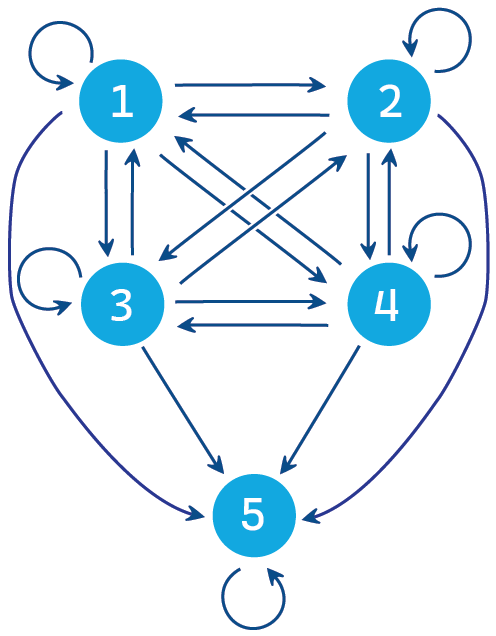

Following [1], build the transition matrix and analyze the resulting model corresponding to the following diagram for HIV-positive patients who are receiving anti-retroviral therapy:

- Assume an initial population of 100,000 people in State 1 and 0 in all other states. Plot the distribution of people among states over ten years. How could you use this to discuss survival and quality of life with a patient who is currently in State 1?

- Discuss the survival and quality of life over ten years for a patient currently in State 3.

- Can you use this model to try to convince sick patients, say in State 3 or State 4, that the effort to take the antiretroviral therapy is worth it?

- Per the model, what fraction of patients remain alive after 150 years? Discuss your findings.

 **Reflect**. 

- Could you use a model like this to recommend policy to a government or healthcare system? What else would you want to know?

TransitionMatrix = [0.7788 0.0828 0.0668 0.0518 0.0198;
    0.1362 0.6862 0.0922 0.0582 0.0272;
    0.0802 0.0682 0.7722 0.0472 0.0322;
    0.044 0.038 0.049 0.814 0.055;
    0 0 0 0 1];

Question 1: 

% Analyze model




Discuss results:

Question 2:

% Analyze model




Discuss results:

Question 3

% Analyze model




Discuss results:

## References

[1] Zingoni, Z. M., Chirwa, T. F., Todd, J., & Musenge, E. (2019). HIV Disease Progression Among Antiretroviral Therapy Patients in Zimbabwe: A Multistate Markov Model. *Frontiers in Public Health*, *7*. https://doi.org/10.3389/fpubh.2019.00326

function CheckExercise1(T,alpha_SI)
if T == eye(3)
    disp("This is the identity matrix. In this system, nothing changes." + newline + ...
        "That is not correct for this system.")
elseif all(subs(T,alpha_SI,0) == T,"all")
    disp("The matrix T should depend on the parameter alpha.")
elseif all(subs(T,alpha_SI,0) == [1 0 0; 0 0 1; 0 0 1],"all") ...
        && all(subs(T,alpha_SI,1) == [0 1 0; 0 0 1; 0 0 1],"all") ...
        && all(subs(T,alpha_SI,2)==[-1 2 0; 0 0 1; 0 0 1],"all")
    disp("That looks like the correct transition matrix.")
else
    disp("Your matrix T does depend on alpha, but not in the correct way." + newline + ...
        "Please think it through and try again.")
end
end

function CheckErgodic(T)
[a,b] = size(T);
if a~=b
    disp("T is not a square matrix.")
else
    if all(T>0)
        if all(sum(T,2)==ones(length(T),1))
            disp("Yes, T is stochastic matrix.")
        else
            disp("This is incorrect, T must be stochastic.")
        end
    elseif all(T>=0)
        disp("This is incorrect. What does it mean to be ergodic?")
    else
        disp("This is incorrect. The transition matrix for a Markov model" + ...
            newline + "is a stochastic matrix. It cannot include negative values.")
    end
end
end